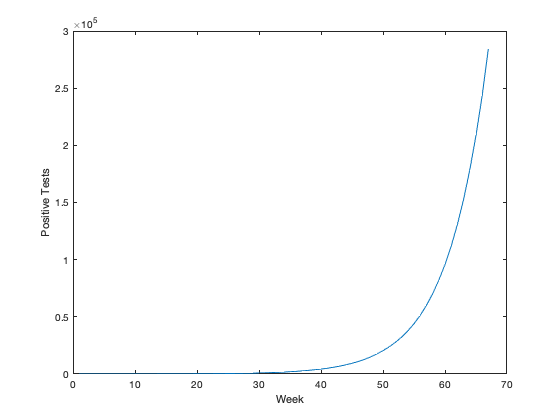

dataset = importdata('/Users/ethanvictormonkhouse/final2021.php'); %import data

%%% Stochastic Simulation %%%

n = 100000; %run simulation n times
test_positive_p = max(dataset.data(:,2))/max(dataset.data(:,1)); %the probability of testing positive
test_positive_with_s_p = max(dataset.data(:,3))/max(dataset.data(:,2)); %the probability of having symptoms with a positive test

r=rand(1,n); %generate either a 0 or 1, n times
tested=(r<=(test_positive_p)); %label whether each value of r is positive or not
r=rand(1,sum(tested)); %for the amount of positive cases, generate a 0 or 1
test_positive=(r<(test_positive_with_s_p)); %label whether each value of r has symptoms or not

tp_sim_s_p = sum(test_positive)/n; %all positive with symptoms cases / population of simulation
tp_sim_ws_p = (length(test_positive) - sum(test_positive))/n; %all positive without symptoms cases / population of simulation

%%% Plot Dataset %%%

plot(dataset.data(:,2)) %plot positive tests vs time
xlabel('Week') %label axis
ylabel('Positive Tests') % label axis

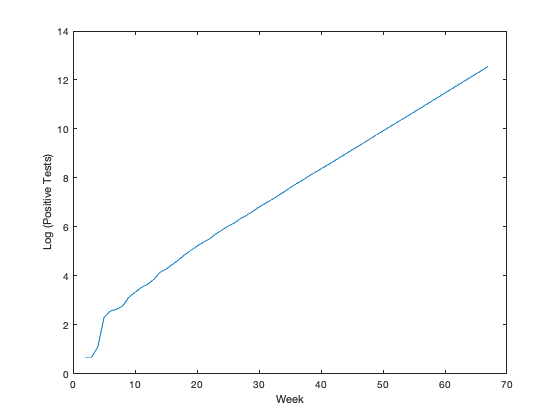


logs = log(dataset.data(:,2)); %calculate log (positive tests) vs time
plot(logs); %plot logs
xlabel('Week') %label axis
ylabel('Log (Positive Tests)') %label axis


random1 = randi(67); %generate random value
random2 = randi(67); %generate random value
estimate_a = abs((logs(random2)-logs(random1))/(random2-random1)) %calculate slope (y2-y1)/(x2-x1)

estimate_a = 0.1553

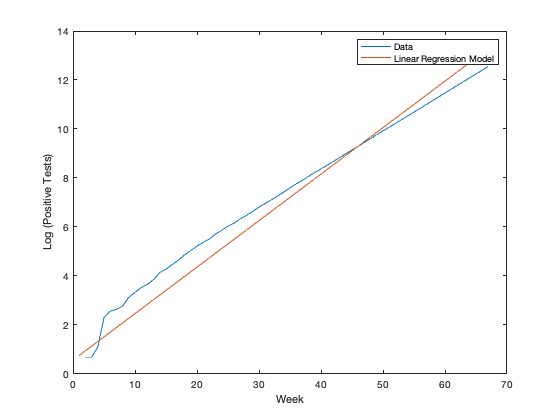


%%% Linear Regression Model %%%

X = (1:size(log(dataset.data(:,2)))).'; %create array of x values corresponding to time (week)
Y = log(dataset.data(:,2)); %create array of y values corresponding to the logarithm of positive tests
Y(1) = 0; %logarithm of zero is infinite, we must exclude from our model

m = 0; %set slope to zero y=mx+C
c = 0; %set y-intercept to zero y=mx+C

stepSize = 0.0001; %set the learning rate of the model
iterations = 10000; %set the number of iterations for the model

for regIndex = 1:iterations
    yValuePrediction = (m*X) + c ; %create an array of Y value predictions
    derivativeSlope = (-2/length(X)) * sum(X .* (Y - yValuePrediction)); %find derivative of sum of actual vs predicted
    derivativeYIntercept = (-2/length(X)) * sum(Y - yValuePrediction); %find derivative of sum of actual vs predicted
    m = m - stepSize * derivativeSlope; %adjust m with step size and calculated derM
    c = c - stepSize * derivativeYIntercept; %adjust m with step size and calculated derC
end  

plot(logs);
hold on; 
plot(X, m*X+c);
xlabel('Week') %label axis
ylabel('Log (Positive Tests)') %label axis
legend('Data', 'Linear Regression Model');
hold off;


%%% bootstrapping %%%

numberOfSamples = 5; %set number of samples to take
sampleSize = 20; %set the size of samples

sampleMeans = zeros(1,numberOfSamples); %initialise means array
sampleIntercepts = zeros(1,numberOfSamples); %initialise intercepts array

for bootIndex = 1:numberOfSamples
    sampleX = sort((randperm(length(logs),sampleSize))).'; %randomly select sample and sort
    sampleY = logs(sampleX); %find corresponding log positive test values
    sampleM = 0; %set slope to zero y=mx+C
    sampleC = 0; %set y-intercept to zero y=mx+C
    for regIndex = 1:iterations %perform gradient descent
        yValuePrediction = (sampleM*sampleX) + sampleC ; %create an array of Y value predictions
        derivativeSampleM = (-2/length(sampleX)) * sum(sampleX .* (sampleY - yValuePrediction)); %find derivative of sum of actual vs predicted
        derivativeSampleC = (-2/length(sampleX)) * sum(sampleY - yValuePrediction); %find derivative of sum of actual vs predicted
        sampleM = sampleM - (stepSize * derivativeSampleM); %adjust m with step size and calculated derM
        sampleC = sampleC - (stepSize * derivativeSampleC); %adjust m with step size and calculated derC
    end
    sampleMeans(bootIndex) = sampleM; %save calculated sample slope
    sampleIntercepts(bootIndex) = sampleC; %save calculated sample intercept
end

%%% confidence interval %%%

populationMeanM = sum(sampleMeans)/length(sampleMeans);
populationStandardDevM = sqrt(var(sampleMeans));

m_clt_lowerBound = populationMeanM - 2*(populationStandardDevM); %CLT Lower Bound
m_clt_upperBound = populationMeanM + 2*(populationStandardDevM); %CLT Upper Bound
fprintf("CLT 95-Percent Confidence Interval is [%f, %f]. \n", m_clt_lowerBound,m_clt_upperBound); %print

CLT 95-Percent Confidence Interval is [0.185727, 0.190661]. 



m_chebyshev_lowerBound = populationMeanM - populationStandardDevM/sqrt(0.05); %Chebyshev Lower Bound
m_chebyshev_upperBound = populationMeanM + populationStandardDevM/sqrt(0.05); %Chebyshev Upper Bound
fprintf("Chebyshev 95-Percent Confidence Interval is [%f, %f]. \n", m_chebyshev_lowerBound,m_chebyshev_upperBound); %print

Chebyshev 95-Percent Confidence Interval is [0.182678, 0.193710]. 



populationMeanC = sum(sampleIntercepts)/length(sampleIntercepts);
populationStandardDevC = sqrt(var(sampleIntercepts));

c_clt_lowerBound = populationMeanC - 2*(populationStandardDevC); %CLT Lower Bound
c_clt_upperBound = populationMeanC + 2*(populationStandardDevC); %CLT Upper Bound
fprintf("CLT 95-Percent Confidence Interval is [%f, %f]. \n", c_clt_lowerBound,c_clt_upperBound); %print

CLT 95-Percent Confidence Interval is [0.439093, 0.746519]. 



c_chebyshev_lowerBound = populationMeanC - populationStandardDevC/sqrt(0.05); %Chebyshev Lower Bound
c_chebyshev_upperBound = populationMeanC + populationStandardDevC/sqrt(0.05); %Chebyshev Upper Bound
fprintf("Chebyshev 95-Percent Confidence Interval is [%f, %f]. \n", c_chebyshev_lowerBound,c_chebyshev_upperBound); %print

Chebyshev 95-Percent Confidence Interval is [0.249093, 0.936518]. 



%%% range of values %%%

valueBetweenInterval = 0.183170 + (0.199076-0.183170).*rand(100,1); %select range of 100 values between Chebyshev interval
valueArray = exp(valueBetweenInterval .* 10)*0.5679; %calculate xk = e^ak(x0), note take x0 = 0.5679

populationMeanK = sum(valueArray)/length(valueArray); %calculate mean
populationStandardDevK = sqrt(var(valueArray)); %calculate std

c_chebyshev_lowerBound = populationMeanK - populationStandardDevK/sqrt(0.05); %Chebyshev Lower Bound
c_chebyshev_upperBound = populationMeanK + populationStandardDevK/sqrt(0.05); %Chebyshev Upper Bound
fprintf("Chebyshev 95-Percent Confidence Interval is [%f, %f]. \n", c_chebyshev_lowerBound,c_chebyshev_upperBound); %print

Chebyshev 95-Percent Confidence Interval is [3.100290, 4.652993]. 
